Now let's begin analyzing the responses of a single cell. First we will plot the average timecourse across all six trials. After interpolation, our frame rate is 5fps. Each cell therefore has a DFF trace that is 2880 samples (or frames) long (5x576).  

load('DFF.mat')

FrameRate = 5;
SamplesPerTrial = 480;
NumTrials = 6;
cell = 1; % this is the cell that we will analyze

After extracting the row vector corresponding to cell #1, we need to rearrange our data into a 2-D matrix with size **SamplesPerTrial** **x NumTrials**.

Use `reshape`, and then `mean(dff_reshaped, dim)` to get the trial-averaged data over your chosen dimension `dim`.

dff_cell = DFF(cell,:); % extract dff trace for our cell
dff_reshaped = reshape(dff_cell,480,6);
dff_avg = mean(dff_reshaped,2);

Plot the trial-averaged response of cell #1.

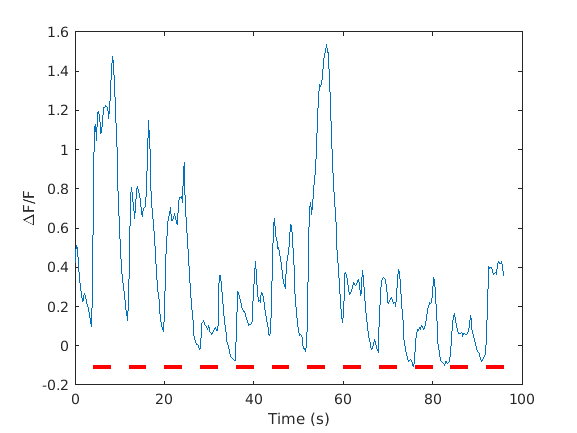

% plot dff_avg        
t = (0:SamplesPerTrial-1)/FrameRate;
plot(t,dff_avg)
hold on;

% plot bars indicating ON period
for i = 1:12
	plot([8*i-4,8*i],min(dff_avg)*ones(1,2),'r','LineWidth',3)
end
xlabel('Time (s)')
ylabel('\DeltaF/F')